% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.

% TEST_GPU_implementation_classification_BC.mlx
% Load a saved trained network and evaluate held-out BC classification performance.
% This script does not train. Run a CPU or GPU training script first, then choose which saved backend to load below.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved Network ----------------
% This file is created by the matching train script. It stores the training options
% and the best trained bias vector. The test action reconstructs deterministic
% weights from saved options, restores best.B, and evaluates the held-out split.
test_seeds = [1 2 3]; % Independently trained initialization seeds used for release test statistics.
diagnostic_seed_index = 1; % Spike diagnostics use one representative seed to keep live plots readable.
test_backend = 'gpu'; % This script evaluates with the GPU implementation.
trained_model_backend = 'auto'; % 'auto' prefers same-backend trained models, then falls back to the other backend.
[model_files, model_file, trained_model_backend] = snn_resolve_seed_model_files(repo_root, 'classification_BC', test_backend, test_seeds, diagnostic_seed_index, trained_model_backend);
save_diagnostic_files = false;  % set true to write diagnostic artifacts as well as displaying inline
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', sprintf('classification_BC_trained_%s_test_gpu_primary', trained_model_backend));
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
missing_model_files = model_files(cellfun(@(f) exist(f, 'file') ~= 2, model_files));
if ~isempty(missing_model_files)
    error('Saved model(s) not found. Run the matching training script for all requested seeds first. First missing file: %s', missing_model_files{1});
end

%% ---------------- Evaluation Overrides ----------------
% model_file is required. batch_size can be lowered if GPU memory is limited.
% Other fields placed in opts override the saved training options for evaluation only.
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file; % Representative seed retained for diagnostics and legacy plot helpers.
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
% result.test.loss is average held-out loss.
% result.test.metric is accuracy (%) for the held-out split.
result = snn_primary_api('test_static', 'classification', test_backend, opts);

[SEED AUDIT] Verified 3 distinct fixed-network hash(es) across 3 seed(s).
Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_test_analysis_20260722_112751_939.mat


fprintf('Testing with %s backend; loaded %s-trained networks for seeds [%s]. Diagnostic seed file:\n%s\n', test_backend, trained_model_backend, num2str(test_seeds), model_file);

Testing with gpu backend; loaded gpu-trained networks for seeds [1  2  3]. Diagnostic seed file:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\classification_BC_gpu_primary_seed001.mat


    Seed     Loss      AccuracyPercent
    ____    _______    _______________

     1      0.12469        94.783     
     2      0.13775        94.783     
     3      0.19754        94.783     



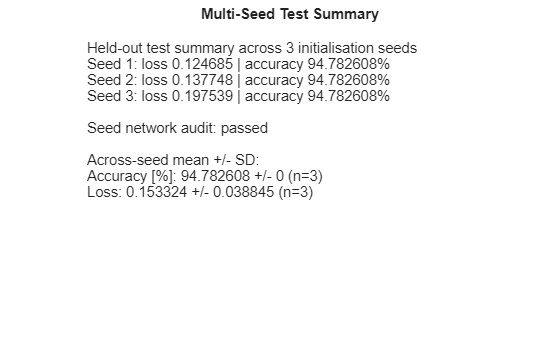

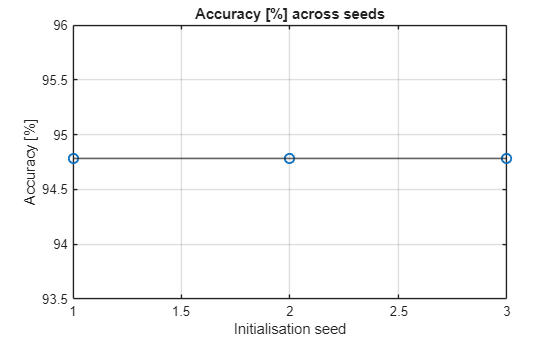

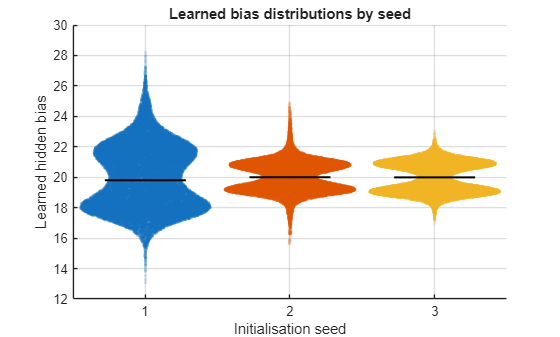

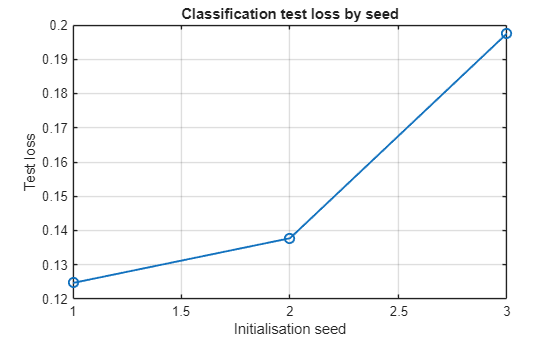

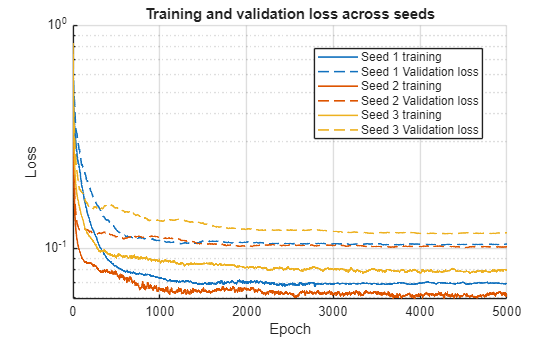

snn_plot_test_result(result);


=== Spiking Diagnostics: bc_test_classification ===
Samples: 8 | Neurons: 32000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 3.76293 Hz | median 2.91667 Hz | 95th percentile 9.16667 Hz
Active neurons: 29692 / 32000 (92.79%)
Silent neurons: 2308 / 32000 (7.21%)
Mean population rate by sample: 3.76293 Hz/neuron
Mean active neurons by sample: 51.71% | silent 48.29%
Total within-sample ISIs counted: 156610
Median per-neuron mean inverse-ISI rate: 10.7014 Hz


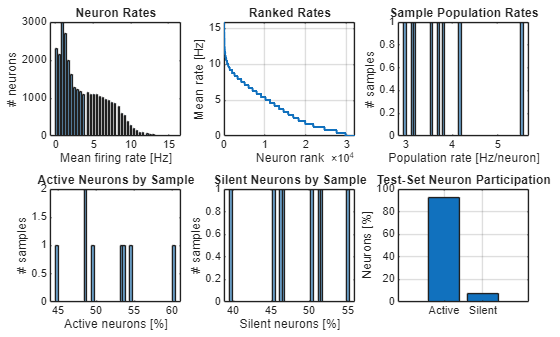

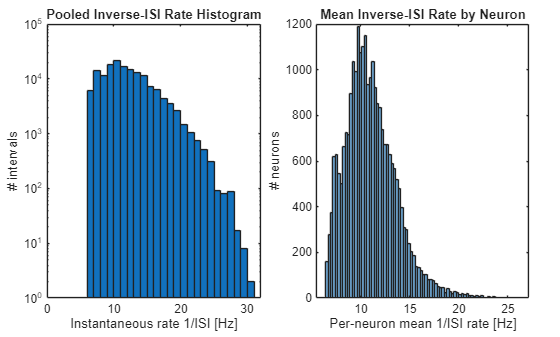

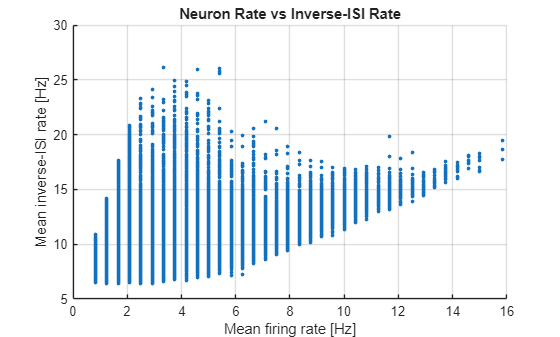

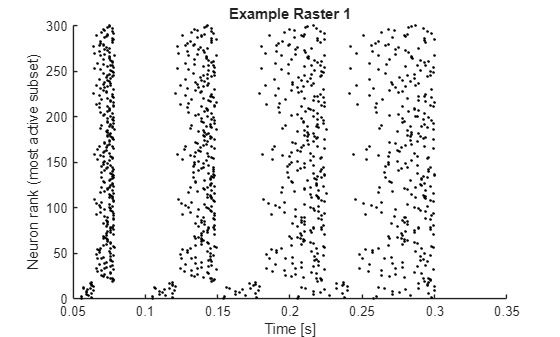

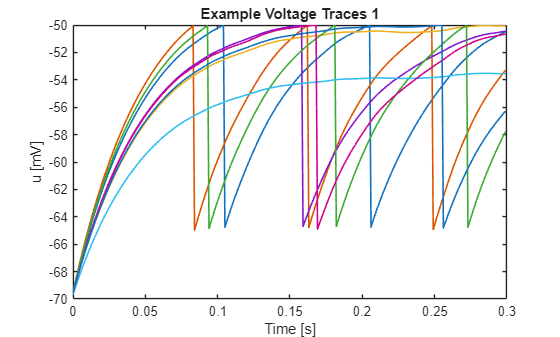

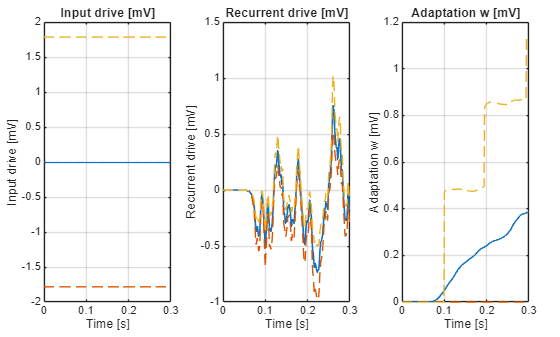

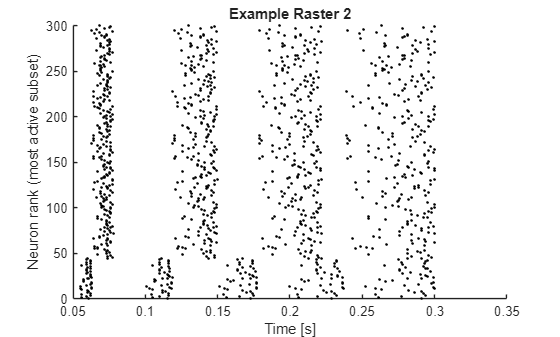

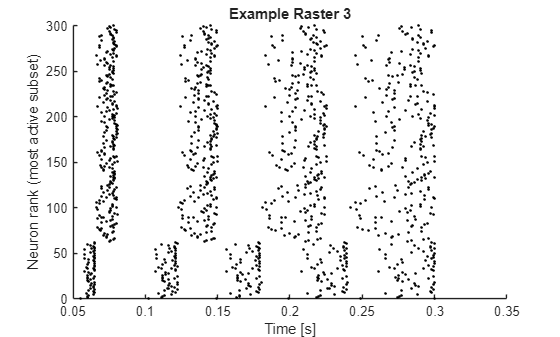

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
% These diagnostics replay the saved trained network through the CPU reference
% to produce spike rasters, firing-rate summaries, ISI histograms, voltage traces,
% input/recurrent/adaptation current summaries. By default they display inline only.
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_static', 'classification', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 92.79%% (29692/32000); silent neurons: 7.21%% (2308/32000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 51.71%%; silent neurons: 48.29%%.


fprintf('Loaded trained network from:\n%s\n', model_file);

Loaded trained network from:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\classification_BC_gpu_primary_seed001.mat


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

      loss: 0.1247
    metric: 94.7826
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]

